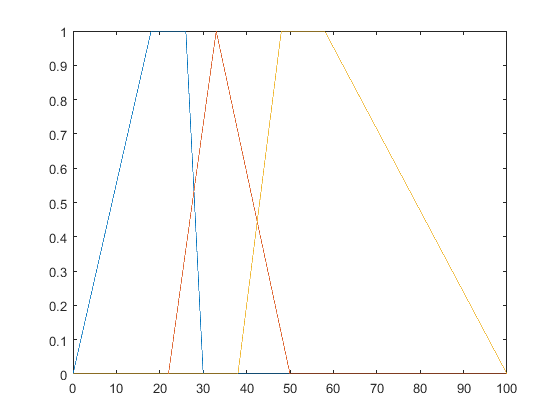

%Sırt Ağrısı Teşhisi İçin Bulanık Mantık Uygulaması
clc;
clear;

global X mu_X  mu_xi;
altsinir_yas=0; ustsinir_yas=100;
altsinir_bmi=0; ustsinir_bmi=45;
altsinir_semptom=0; ustsinir_semptom=100;
 
tedavi_altsinir=0; tedavi_ustsinir=100;
teshis_altsinir=0; teshis_ustsinir=100;
 
%numerik girisler
yas_xi=40; bmi_xi=19; semptom_xi=52.3;
tedavi_xi=0; teshis_xi=0;

  
%Numerik girislerin, girsi cikis uyelk fonk ,Bulanik kumelerin tanimlanmaasi
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%1. Yash girisine ait uyelik fonksiyonlari ve bulaniklashtirma
%Uyelik derecelerinin tanimlanmasi
trapezoid(altsinir_yas,0,18,26,30,ustsinir_yas,yas_xi); x_genc=X; genc_xi=mu_xi; mu_genc=mu_X;
hold on;
triangle(altsinir_yas,22,33,50,ustsinir_yas,yas_xi); x_orta=X; orta_xi=mu_xi; mu_orta=mu_X;

trapezoid(altsinir_yas,38,48,58,100, ustsinir_yas,yas_xi); x_yasli=X; yasli_xi=mu_xi; mu_yasli=mu_X;
    hold off;

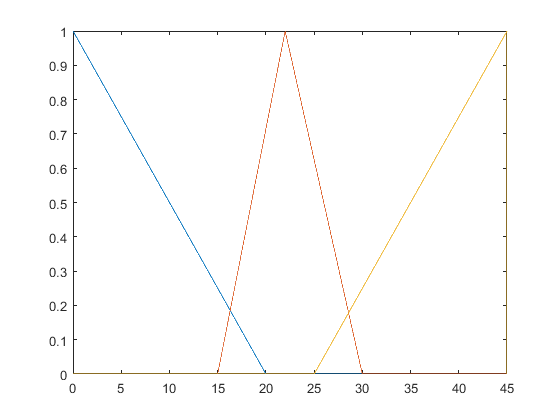


%2. Vucut kutle indeksine ait uyelik fonk girisleri...
triangle(altsinir_bmi,0,0,20,ustsinir_bmi, bmi_xi);  bmi_dusuk_xi=mu_xi; 
hold on;
triangle(altsinir_bmi,15,22,30,ustsinir_bmi, bmi_xi);  bmi_orta_xi=mu_xi; 
triangle(altsinir_bmi,25,45,45,ustsinir_bmi, bmi_xi); bmi_yuksek_xi=mu_xi; 
hold off;

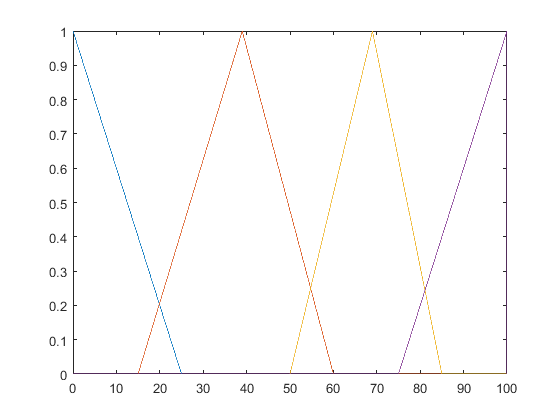


%3. Semptomlara ait uyelik fonk girisleri ...
triangle(altsinir_semptom,0,0,25,ustsinir_semptom,semptom_xi);  semptom_az_xi=mu_xi; 
hold on;
triangle(altsinir_semptom,15,39,60,ustsinir_semptom,semptom_xi);  semptom_orta_xi=mu_xi; 
triangle(altsinir_semptom,50,69,85,ustsinir_semptom,semptom_xi);  semptom_yuksek_xi=mu_xi; 
triangle(altsinir_semptom,75,100,100,ustsinir_semptom,semptom_xi);  semptom_cokyuksek_xi=mu_xi;
hold off;

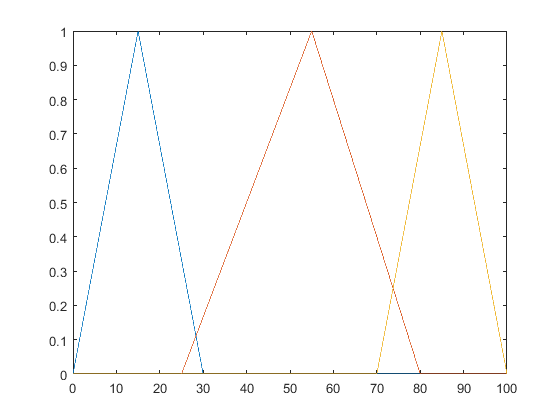


%Tedavi cikis uyelik fonk
triangle(tedavi_altsinir,0,15,30,tedavi_ustsinir,tedavi_xi); dinlenme_mu=mu_X;
hold on;
triangle(tedavi_altsinir,25,55,80,tedavi_ustsinir,tedavi_xi);  ilaclar_mu=mu_X;
triangle(tedavi_altsinir,70,85,100,tedavi_ustsinir,tedavi_xi);  ameliyat_mu=mu_X;
hold off;

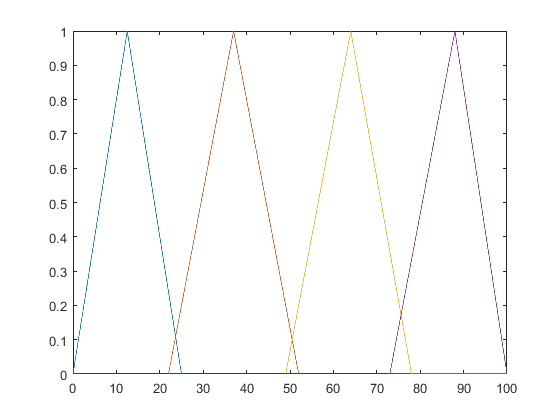


%Teshis cikis uyelik fonk
triangle(teshis_altsinir,0,12.5,25,teshis_ustsinir,teshis_xi); fitikDaralma_x=X;  fitikDaralma_mu=mu_X;
hold on;
triangle(teshis_altsinir,22,37,52,teshis_ustsinir,teshis_xi); diskKaymasi_x=X;  diskKaymasi_mu=mu_X;
triangle(teshis_altsinir,49,64,78,teshis_ustsinir,teshis_xi); VertebralarinArtriti_x=X;  VertebralarinArtriti_mu=mu_X;
triangle(teshis_altsinir,73,88,100,teshis_ustsinir,teshis_xi); osteoporos_x=X;  osteoporos_mu=mu_X;

hold off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Kurallarin tanimlanmasi ve gecerlilik derecelerin hesaplanmasi
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ve baglaci olarak burada min kullanilmistir
mu_kural1=min(min(genc_xi, bmi_yuksek_xi), semptom_cokyuksek_xi);
mu_kural4=min(min(orta_xi,bmi_yuksek_xi),semptom_cokyuksek_xi);
mu_kural7=min(min(yasli_xi,bmi_orta_xi),semptom_cokyuksek_xi);
mu_kural8=min(min(yasli_xi,bmi_yuksek_xi),semptom_cokyuksek_xi);
mu_kural10=min(min(genc_xi,bmi_yuksek_xi),semptom_yuksek_xi);
mu_kural11=min(min(orta_xi,bmi_orta_xi),semptom_yuksek_xi);
mu_kural13=min(min(genc_xi,bmi_yuksek_xi),semptom_az_xi);
mu_kural15=min(min(genc_xi,bmi_dusuk_xi),semptom_orta_xi);
mu_kural16=min(min(orta_xi,bmi_dusuk_xi),semptom_orta_xi);

%%%%%%%%%%%%%%%%%%%%%%%%%%

%Gerektirme islemi ile Tedavi kurallara ait sonuc kumelerinin belirlenmesi
%gerektirme operatoru olarak prod * kullanilmistir
%%%%%%%%%%%%%
mu_sonuc1=mu_kural1*dinlenme_mu;
mu_sonuc4=mu_kural4*ameliyat_mu;
mu_sonuc7=mu_kural7*ameliyat_mu;
mu_sonuc8=mu_kural8*ameliyat_mu;
mu_sonuc10=mu_kural10*ilaclar_mu;
mu_sonuc11=mu_kural11*ilaclar_mu;
mu_sonuc13=mu_kural13*ilaclar_mu;
mu_sonuc15=mu_kural15*dinlenme_mu;
mu_sonuc16=mu_kural16*ameliyat_mu;

%%%%%%%%%%%%%%%%
%Gerektirme islemi ile Teshis kurallari icin sonuc kumelerinin belirlenmesi
%gerektirme operatoru olarak prod * kullanilmistir
mu_son1=mu_kural1*fitikDaralma_mu;
mu_son4=mu_kural4*diskKaymasi_mu;
mu_son7=mu_kural7*diskKaymasi_mu;
mu_son8=mu_kural8*diskKaymasi_mu;
mu_son10=mu_kural10*VertebralarinArtriti_mu;
mu_son11=mu_kural11*VertebralarinArtriti_mu;
mu_son13=mu_kural13*fitikDaralma_mu;
mu_son15=mu_kural15*osteoporos_mu;
mu_son16=mu_kural16*osteoporos_mu;

%Tedavi birlestirme operatoru olarak max kullanilmistir
mu_birlestirme=max(max(max(max(mu_sonuc1,mu_sonuc4),max(mu_sonuc7,mu_sonuc8)),max(max(mu_sonuc10,mu_sonuc11),max(mu_sonuc13,mu_sonuc15))),mu_sonuc16);
%1.cikis
% TEdavi cikis bulanik kumesinin grafiginin cizdirilmesi
plot(X,mu_birlestirme);
hold on;
%Duruulastirma islemi ve Durulastirma sonucunu Grafikte gosterimi
%durulastirma operatoru olarak agirlik merkezi kullanilmistir
toplam_alan=sum(mu_birlestirme); %mu_birlestirme nedir?
if toplam_alan==0
    'Agirlk merkezi yonteminde toplam alan 0 dir';
end
z=sum(mu_birlestirme.*X)/toplam_alan

z = 58.7553

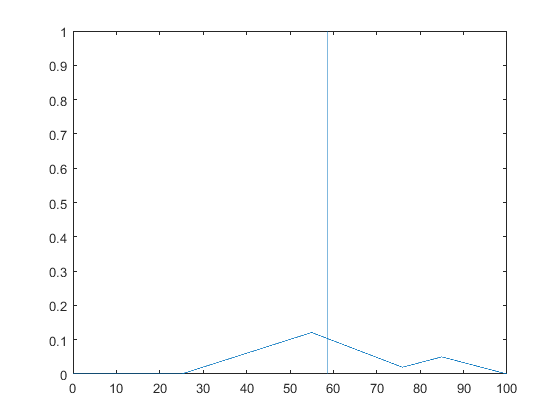

h=[z z z z z z z z z z z];
line(h,0:0.1:1);%durulastirma sonucu
hold off;


%2cikis

%Teshis birlestirme operatoru olarak max kullanilmistir
mu_birlestirme2=max(max(max(max(mu_son1,mu_son4),max(mu_son7,mu_son8)),max(max(mu_son10,mu_son11),max(mu_son13,mu_son15))),mu_son16);
 
% TEshis cikis bulanik kumesinin grafiginin cizdirilmesi
plot(X,mu_birlestirme2);
hold on;
%teshis durulastirma
toplam_alan2=sum(mu_birlestirme2); %mu_birlestirme nedir?
if toplam_alan2==0
    'Agirlk merkezi yonteminde toplam alan 0 dir';
end
z1=sum(mu_birlestirme2.*X)/toplam_alan2

z1 = 70.0758

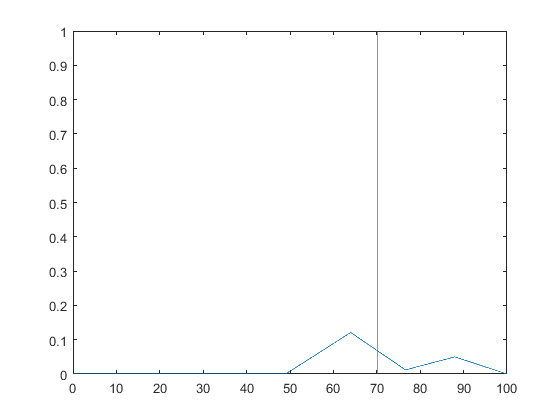

h1=[z1 z1 z1 z1 z1 z1 z1 z1 z1 z1 z1];
line(h1,0:0.1:1);%durulastirma sonucu
hold off;